ens = simulationEnsembleDatastore(fullfile('.','Data'));

     1     2



ens.DataVariables

ans = 25×1 string array
    "BearingFault"
    "BlockingFault"
    "LeakFault"
    "SimulationInput"
    "SimulationMetadata"
    "fPeak"
    "iMotor_meas"
    "pHigh"
    "pIn_meas"
    "pKurtosis"
    "pLow"
    "pMid"
    "pOut_meas"
    "qCSRange"
    "qCrest"
    "qIn_meas"
    "qKurtosis"
    "qMAD"
    "qMean"
    "qOut_meas"
    "qPeak2Peak"
    "qRMS"
    "qSkewness"
    "qVar"
    "wMotor_meas"


ens.SelectedVariables = ["qOut_meas", "SimulationInput"];
reset(ens)
data = read(ens)

data = 1×2 table
        qOut_meas                SimulationInput        
    __________________    ______________________________

    {2001×1 timetable}    {1×1 Simulink.SimulationInput}


[flow,flowP,flowF,faultValues] = preprocess(data);

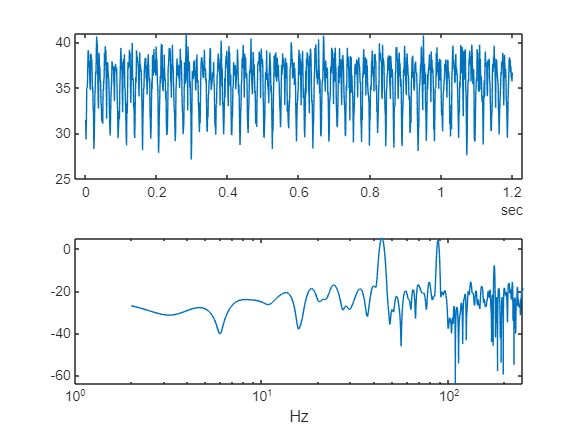

% Figure with nominal
subplot(211);
plot(flow.Time,flow.Data);
subplot(212);
semilogx(flowF,pow2db(flowP));
xlabel('Hz')

ens.DataVariables = [ens.DataVariables; ...
    "fPeak"; "pLow"; "pMid"; "pHigh"; "pKurtosis"; ...
    "qMean"; "qVar"; "qSkewness"; "qKurtosis"; ...
    "qPeak2Peak"; "qCrest"; "qRMS"; "qMAD"; "qCSRange"];
ens.ConditionVariables = ["LeakFault","BlockingFault","BearingFault"];

feat = extractCI(flow,flowP,flowF);
dataToWrite = [faultValues, feat];
writeToLastMemberRead(ens,dataToWrite{:})

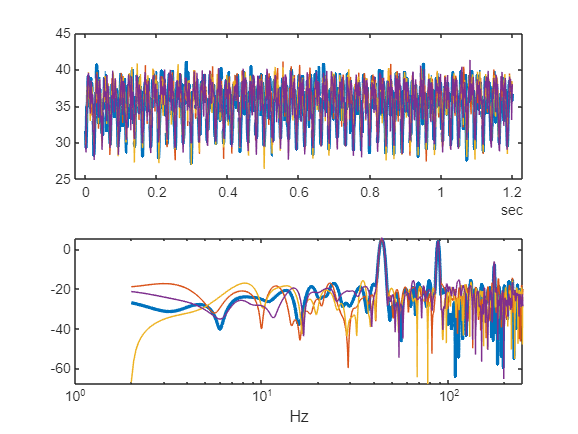

Error using predmaint.internal.pmdata.PMDatastore/read (line 192)
Variable does not exist.

%Figure with nominal and faults
figure,
subplot(211);
lFlow = plot(flow.Time,flow.Data,'LineWidth',2);
subplot(212);
lFlowP = semilogx(flowF,pow2db(flowP),'LineWidth',2);
xlabel('Hz')
ct = 1;
lColors = get(lFlow.Parent,'ColorOrder');
lIdx = 2;

% Loop over all members in the ensemble, preprocess 
% and compute the features for each member
while hasdata(ens)
    
    % Read member data
    data = read(ens);
    
    % Preprocess and extract features from the member data
    [flow,flowP,flowF,faultValues] = preprocess(data);
    feat = extractCI(flow,flowP,flowF);
    
    % Add the extracted feature values to the member data
    dataToWrite = [faultValues, feat];
    writeToLastMemberRead(ens,dataToWrite{:})
    
    % Plot member signal and spectrum for every 100th member
    if mod(ct,100) == 0
        line('Parent',lFlow.Parent,'XData',flow.Time,'YData',flow.Data, ...
            'Color', lColors(lIdx,:));
        line('Parent',lFlowP.Parent,'XData',flowF,'YData',pow2db(flowP), ...
            'Color', lColors(lIdx,:));
        if lIdx == size(lColors,1)
            lIdx = 1;
        else
            lIdx = lIdx+1;
        end
    end
    ct = ct + 1;
end

% Get data to design a classifier.
reset(ens)
ens.SelectedVariables = [...
    "fPeak","pLow","pMid","pHigh","pKurtosis",...
    "qMean","qVar","qSkewness","qKurtosis",...
    "qPeak2Peak","qCrest","qRMS","qMAD","qCSRange",...
    "LeakFault","BlockingFault","BearingFault"];
idxLastFeature = 14;

% Load the condition indicator data into memory
data = gather(tall(ens));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: 81% complete
Evaluation 81% complete


Error using predmaint.internal.pmdata.PMDatastore/read (line 192)
Variable does not exist.
Learn more about errors encountered during GATHER.

Error in tall/gather (line 50)

data(1:10,:)

% Convert the fault variable values to flags
data.LeakFlag = data.LeakFault > 1e-6;
data.BlockingFlag = data.BlockingFault < 0.8;
data.BearingFlag = data.BearingFault > 0; 
data.CombinedFlag = data.LeakFlag+2*data.BlockingFlag+4*data.BearingFlag;

data

data = 400×21 table
    fPeak      pLow       pMid     pHigh     pKurtosis    qMean      qVar     qSkewness    qKurtosis    qPeak2Peak    qCrest     qRMS      qMAD     qCSRange    LeakFault    BlockingFault    BearingFault    LeakFlag    BlockingFlag    BearingFlag    CombinedFlag
    ______    _______    ______    ______    _________    ______    ______    _________    _________    __________    ______    ______    ______

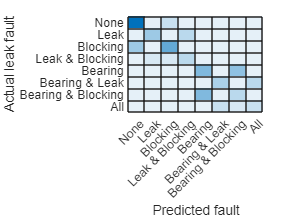

%For SVM

rng('default') % for reproducibility
predictors = data(:,1:idxLastFeature); 
response = data.CombinedFlag;
cvp = cvpartition(size(predictors,1),'KFold',5);

% Create and train the classifier
template = templateSVM(...
    'KernelFunction', 'polynomial', ...
    'PolynomialOrder', 2, ...
    'KernelScale', 'auto', ...
    'BoxConstraint', 1, ...
    'Standardize', true);
combinedClassifier = fitcecoc(...
    predictors(cvp.training(1),:), ...
    response(cvp.training(1),:), ...
    'Learners', template, ...
    'Coding', 'onevsone', ...
    'ClassNames', [0; 1; 2; 3; 4; 5; 6; 7]);

% Check performance by computing and plotting the confusion matrix
actualValue = response(cvp.test(1),:);
predictedValue = predict(combinedClassifier, predictors(cvp.test(1),:));
confdata = confusionmat(actualValue,predictedValue);
figure,
labels = {'None', 'Leak','Blocking', 'Leak & Blocking', 'Bearing', ...
    'Bearing & Leak', 'Bearing & Blocking', 'All'};
h = heatmap(confdata, ...
    'YLabel', 'Actual leak fault', ...
    'YDisplayLabels', labels, ...
    'XLabel', 'Predicted fault', ...
    'XDisplayLabels', labels, ...
    'ColorbarVisible','off');


% Compute the overall accuracy of the classifier
sum(diag(confdata))/sum(confdata(:))

ans = 0.6125

% Compute the accuracy of the classifier at predicting 
% that there is a fault
1-sum(confdata(2:end,1))/sum(confdata(:))

ans = 0.9375

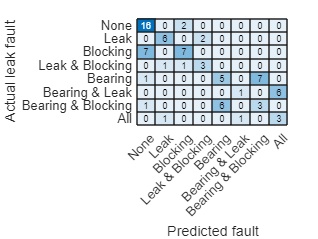

%For KNN

rng('default') % for reproducibility

predictors = data(:,1:idxLastFeature);
response = data.CombinedFlag;
cvp = cvpartition(size(predictors,1),'KFold',5);
% Create and train the classifier
template = templateKNN('NumNeighbors',5,'Standardize',1);
combinedClassifier = fitcecoc(...
predictors(cvp.training(1),:), ...
response(cvp.training(1),:), ...
'Learners', template, ...
'Coding', 'onevsone', ...
'ClassNames', [0; 1; 2; 3; 4; 5; 6; 7]);

% Check performance by computing and plotting the confusion matrix
actualValue = response(cvp.test(1),:);
predictedValue = predict(combinedClassifier, predictors(cvp.test(1),:));
confdata = confusionmat(actualValue,predictedValue);
figure,
labels = {'None', 'Leak','Blocking', 'Leak & Blocking', 'Bearing', ...
    'Bearing & Leak', 'Bearing & Blocking', 'All'};
h = heatmap(confdata, ...
    'YLabel', 'Actual leak fault', ...
    'YDisplayLabels', labels, ...
    'XLabel', 'Predicted fault', ...
    'XDisplayLabels', labels, ...
    'ColorbarVisible','off');


% Compute the overall accuracy of the classifier
sum(diag(confdata))/sum(confdata(:))

ans = 0.5500

% Compute the accuracy of the classifier at predicting 
% that there is a fault
1-sum(confdata(2:end,1))/sum(confdata(:))

ans = 0.8875

%Decision Tree

a=5

a = 5

a

a = 5

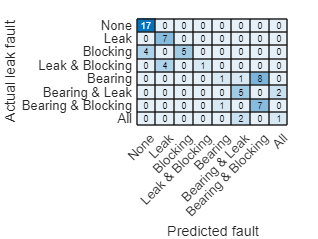


rng('default') % for reproducibility
predictors = data(:,1:idxLastFeature);
response = data.CombinedFlag;
cvp = cvpartition(size(predictors,1),'KFold',6);
% Create and train the classifier
template = templateTree('Surrogate','on','MaxNumSplits',1);

%t = templateEnsemble('AdaBoostM1',50,template,'LearnRate',0.9);

combinedClassifier = fitcecoc(...
predictors(cvp.training(1),:), ...
response(cvp.training(1),:), ...
'Learners', template, ...
'Coding', 'onevsone', ...
'ClassNames', [0; 1; 2; 3; 4; 5; 6; 7]);

% Check performance by computing and plotting the confusion matrix
actualValue = response(cvp.test(1),:);
predictedValue = predict(combinedClassifier, predictors(cvp.test(1),:));
confdata = confusionmat(actualValue,predictedValue);
figure,
labels = {'None', 'Leak','Blocking', 'Leak & Blocking', 'Bearing', ...
    'Bearing & Leak', 'Bearing & Blocking', 'All'};
h = heatmap(confdata, ...
    'YLabel', 'Actual leak fault', ...
    'YDisplayLabels', labels, ...
    'XLabel', 'Predicted fault', ...
    'XDisplayLabels', labels, ...
    'ColorbarVisible','off');


% Compute the overall accuracy of the classifier
sum(diag(confdata))/sum(confdata(:))

ans = 0.6667

% Compute the accuracy of the classifier at predicting 
% that there is a fault
1-sum(confdata(2:end,1))/sum(confdata(:))

ans = 0.9394

%Linear

a=5

a = 5

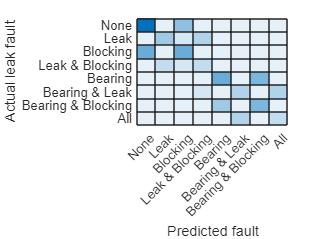


rng('default') % for reproducibility
predictors = data(:,1:idxLastFeature);
response = data.CombinedFlag;
cvp = cvpartition(size(predictors,1),'KFold',5);
% Create and train the classifier
template = templateLinear();
combinedClassifier = fitcecoc(...
predictors(cvp.training(1),:), ...
response(cvp.training(1),:), ...
'Learners', template, ...
'Coding', 'onevsone', ...
'ClassNames', [0; 1; 2; 3; 4; 5; 6; 7]);

% Check performance by computing and plotting the confusion matrix
actualValue = response(cvp.test(1),:);
predictedValue = predict(combinedClassifier, predictors(cvp.test(1),:));
confdata = confusionmat(actualValue,predictedValue);
figure,
labels = {'None', 'Leak','Blocking', 'Leak & Blocking', 'Bearing', ...
    'Bearing & Leak', 'Bearing & Blocking', 'All'};
h = heatmap(confdata, ...
    'YLabel', 'Actual leak fault', ...
    'YDisplayLabels', labels, ...
    'XLabel', 'Predicted fault', ...
    'XDisplayLabels', labels, ...
    'ColorbarVisible','off');


% Compute the overall accuracy of the classifier
sum(diag(confdata))/sum(confdata(:))

ans = 0.5500

% Compute the accuracy of the classifier at predicting 
% that there is a fault
1-sum(confdata(2:end,1))/sum(confdata(:))

ans = 0.9125

%Discriminant

a=5

a = 5

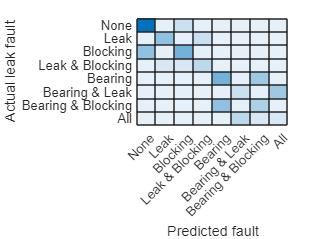


rng('default') % for reproducibility
predictors = data(:,1:idxLastFeature);
response = data.CombinedFlag;
cvp = cvpartition(size(predictors,1),'KFold',5);

% Create and train the classifier
template = templateDiscriminant('DiscrimType','pseudoLinear');
combinedClassifier = fitcecoc(...
predictors(cvp.training(1),:), ...
response(cvp.training(1),:), ...
'Learners', template, ...
'Coding', 'onevsone', ...
'ClassNames', [0; 1; 2; 3; 4; 5; 6; 7]);

%CVMdl = crossval(combinedClassifier);
%genError = kfoldLoss(CVMdl);
%genError

% Check performance by computing and plotting the confusion matrix
actualValue = response(cvp.test(1),:);
predictedValue = predict(combinedClassifier, predictors(cvp.test(1),:));
confdata = confusionmat(actualValue,predictedValue);
figure,
labels = {'None', 'Leak','Blocking', 'Leak & Blocking', 'Bearing', ...
    'Bearing & Leak', 'Bearing & Blocking', 'All'};
h = heatmap(confdata, ...
    'YLabel', 'Actual leak fault', ...
    'YDisplayLabels', labels, ...
    'XLabel', 'Predicted fault', ...
    'XDisplayLabels', labels, ...
    'ColorbarVisible','off');


% Compute the overall accuracy of the classifier
sum(diag(confdata))/sum(confdata(:))

ans = 0.6000

% Compute the accuracy of the classifier at predicting 
% that there is a fault
1-sum(confdata(2:end,1))/sum(confdata(:))

ans = 0.9250

%Naive Bayes

a=5

a = 5

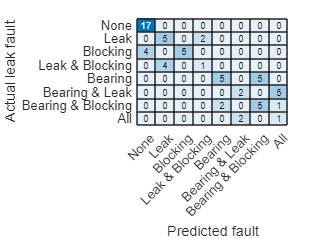


rng('default') % for reproducibility
predictors = data(:,1:idxLastFeature);
response = data.CombinedFlag;
cvp = cvpartition(size(predictors,1),'KFold',6);

% Create and train the classifier
template = templateNaiveBayes(); %'DistributionNames','kernel');
combinedClassifier = fitcecoc(...
predictors(cvp.training(1),:), ...
response(cvp.training(1),:), ...
'Learners', template, ...
'Coding', 'onevsone', ...
'ClassNames', [0; 1; 2; 3; 4; 5; 6; 7]);

% Check performance by computing and plotting the confusion matrix
actualValue = response(cvp.test(1),:);
predictedValue = predict(combinedClassifier, predictors(cvp.test(1),:));
confdata = confusionmat(actualValue,predictedValue);
figure,
labels = {'None', 'Leak','Blocking', 'Leak & Blocking', 'Bearing', ...
    'Bearing & Leak', 'Bearing & Blocking', 'All'};
h = heatmap(confdata, ...
    'YLabel', 'Actual leak fault', ...
    'YDisplayLabels', labels, ...
    'XLabel', 'Predicted fault', ...
    'XDisplayLabels', labels, ...
    'ColorbarVisible','off');


% Compute the overall accuracy of the classifier
sum(diag(confdata))/sum(confdata(:))

ans = 0.6212

% Compute the accuracy of the classifier at predicting 
% that there is a fault
1-sum(confdata(2:end,1))/sum(confdata(:))

ans = 0.9394

%Naive Bayes with cross val

a=5

a = 5


rng('default') % for reproducibility
predictors = data(:,1:idxLastFeature);
response = data.CombinedFlag;
cvp = cvpartition(size(predictors,1),'KFold',4);

% Create and train the classifier
template = templateNaiveBayes(); %'DistributionNames','kernel');
combinedClassifier = fitcecoc(...
predictors(cvp.training(1),:), ...
response(cvp.training(1),:), ...
'Learners', template, ...
'Coding', 'onevsone', ...
'ClassNames', [0; 1; 2; 3; 4; 5; 6; 7]);
%'CrossVal','on');

CVMdl = crossval(combinedClassifier);

genError = kfoldLoss(CVMdl);
genError

genError = 0.4167


[label,NegLoss,PBScore] = kfoldPredict(combinedClassifier);

Check for incorrect argument data type or missing argument in call to function 'kfoldPredict'.

C = confusionchart(response(cvp.training(1),:),label);
C

% Compute the overall accuracy of the classifier
sum(diag(C))/sum(C(:))
% Compute the accuracy of the classifier at predicting 
% that there is a fault
1-sum(C(2:end,1))/sum(C(:))



label
confdata1 = confusionmat(response(cvp.test(1),:), label);
%PBScore
%NegLoss

% Check performance by computing and plotting the confusion matrix
actualValue = response(cvp.test(1),:);

predictedValue = predict(combinedClassifier, predictors(cvp.test(1),:));
%confdata = confusionmat(actualValue,predictedValue);
figure,
labels = {'None', 'Leak','Blocking', 'Leak & Blocking', 'Bearing', ...
    'Bearing & Leak', 'Bearing & Blocking', 'All'};
h = heatmap( confdata1, ...
    'YLabel', 'Actual leak fault', ...
    'YDisplayLabels', labels, ...
    'XLabel', 'Predicted fault', ...
    'XDisplayLabels', labels, ...
    'ColorbarVisible','off');

% Compute the overall accuracy of the classifier
sum(diag(confdata1))/sum(confdata1(:))
% Compute the accuracy of the classifier at predicting 
% that there is a fault
1-sum(confdata(2:end,1))/sum(confdata(:))

for i=1:50: 400

predictedValue = predict(combinedClassifier, predictors(i,:));

%disp(" -> Because Leak fault value is <= 1e-6");

%disp(" -> Because Blocking fault value is >= 0.8;");

%disp(" -> Because Bearing fault <= 0");

switch predictedValue

case 0

disp("No faults in the system");

case 1 %001

disp("System contains one fault :");

disp(" Leak Fault -> Because Leak fault value is <= 1e-6");

case 2 %010

disp("System contains one fault : ");

disp(" Blocking Fault -> Because Blocking fault value is >= 0.8;");

case 3 %011

disp("System contains two faults : ");

disp(" tLeak Fault -> Because Leak fault value is <= 1e-6");

disp(" Blocking Fault -> Because Blocking fault value is >= 0.8;");

case 4 %100

disp("System contains one fault :");

disp(" Bearing Fault -> Because Bearing fault <= 0");

case 5 %101

disp("System contains two faults :");

disp(" Leak Fault -> Because Leak fault value is <= 1e-6");

disp(" Bearing Fault -> Because Bearing fault <= 0");

case 6 %110

disp("System contains two faults : ");

disp(" Blocking Fault -> Because Blocking fault value is >= 0.8;");

disp(" Bearing Fault -> Because Bearing fault <= 0");

case 7 %all faults

disp("System contains three faults :");

disp(" Leak Fault -> Because Leak fault value is <= 1e-6");

disp(" Blocking Fault -> Because Blocking fault value is >= 0.8;");

disp(" Bearing Fault -> Because Bearing fault <= 0");

otherwise

disp("Something went wrong :(");

end

end

function [flow,flowSpectrum,flowFrequencies,faultValues] = preprocess(data)
% Helper function to preprocess the logged reciprocating pump data.

% Remove the 1st 0.8 seconds of the flow signal
tMin = seconds(0.8);
flow = data.qOut_meas{1};
flow = flow(flow.Time >= tMin,:);
flow.Time = flow.Time - flow.Time(1);

% Ensure the flow is sampled at a uniform sample rate
flow = retime(flow,'regular','linear','TimeStep',seconds(1e-3));

% Remove the mean from the flow and compute the flow spectrum
fA = flow;
fA.Data = fA.Data - mean(fA.Data);
[flowSpectrum,flowFrequencies] = pspectrum(fA,'FrequencyLimits',[2 250]);

% Find the values of the fault variables from the SimulationInput
simin = data.SimulationInput{1};
vars = {simin.Variables.Name};
idx = strcmp(vars,'leak_cyl_area_WKSP');
LeakFault = simin.Variables(idx).Value;
idx = strcmp(vars,'block_in_factor_WKSP');
BlockingFault = simin.Variables(idx).Value;
idx = strcmp(vars,'bearing_fault_frict_WKSP');
BearingFault = simin.Variables(idx).Value;

% Collect the fault values in a cell array
faultValues = {...
    'LeakFault', LeakFault, ...
    'BlockingFault', BlockingFault, ... 
    'BearingFault', BearingFault};
end

function ci = extractCI(flow,flowP,flowF)
% Helper function to extract condition indicators from the flow signal 
% and spectrum.

% Find the frequency of the peak magnitude in the power spectrum.
pMax = max(flowP);
fPeak = flowF(flowP==pMax);

% Compute the power in the low frequency range 10-20 Hz.
fRange = flowF >= 10 & flowF <= 20;
pLow = sum(flowP(fRange));

% Compute the power in the mid frequency range 40-60 Hz.
fRange = flowF >= 40 & flowF <= 60;
pMid = sum(flowP(fRange));

% Compute the power in the high frequency range >100 Hz.
fRange = flowF >= 100;
pHigh = sum(flowP(fRange));

% Find the frequency of the spectral kurtosis peak
[pKur,fKur] = pkurtosis(flow);
pKur = fKur(pKur == max(pKur));

% Compute the flow cumulative sum range.
csFlow = cumsum(flow.Data);
csFlowRange = max(csFlow)-min(csFlow);

% Collect the feature and feature values in a cell array. 
% Add flow statistic (mean, variance, etc.) and common signal 
% characteristics (rms, peak2peak, etc.) to the cell array.
ci = {...
    'qMean', mean(flow.Data), ...
    'qVar',  var(flow.Data), ...
    'qSkewness', skewness(flow.Data), ...
    'qKurtosis', kurtosis(flow.Data), ...
    'qPeak2Peak', peak2peak(flow.Data), ...
    'qCrest', peak2rms(flow.Data), ...
    'qRMS', rms(flow.Data), ...
    'qMAD', mad(flow.Data), ...
    'qCSRange',csFlowRange, ...
    'fPeak', fPeak, ...
    'pLow', pLow, ...
    'pMid', pMid, ...
    'pHigh', pHigh, ...
    'pKurtosis', pKur(1)};
end